# **EECE-5666 (DSP): Homework-4**

### Due on February 25, 2020 by 11:59 pm via submission portal. 

#### NAME: McElhinney, Owen

#### Instructions:

- You are required to complete this assignment using Live Editor.

- Enter your MATLAB script in the spaces provided. If it contains a plot, the plot will be displayed after the script.

- All your plots must be properly labeled and should have appropriate titles to get full credit.

- Use the equation editor to typeset mathematical material such as variables, equations, etc. 

- After completing this assignment, export this Live script to PDF and submit the PDF file through the provided submission portal.

- Late submissions will not be accepted since solutions will be released at 12 midnight on the due date. If you have not completed the entire assignment, submit whatever you have finished by the deadline.

**Reading Assignment**: Chapter 5 sections 5.1 through 5.8 and Chapter 6 sections 6.1 through 6.4 from the Manolakis and Ingle textbook. 

**Default Plot Parameters:**

set(0,'defaultfigurepaperunits','points','defaultfigureunits','points');

set(0,'defaultaxesfontsize',10);
set(0,'defaultaxestitlefontsize',1.4,'defaultaxeslabelfontsize',1.2);

## Problem-1: Text Problem 5.23

An LTI system is described by the difference equation


$$y[n] = b x[n] + 0.8y[n-1] - 0.81y[n-2].$$


**(a)** Determine the frequency response $H(\mathrm{e}^{\j\omega})$ of the system in terms of $b$.

**Solution**: 


$$H(e^{j\omega}) = \frac{b}{1 - 0.8e^{-j\omega}+0.81e^{-2j\omega}}$$


**(b)** Determine $b$ so that $$\bigl|H(\mathrm{e}^{\j\omega})\bigr|_{\max} = 1$$. Plot the resulting magnitude response.

**Solution**: 

% Use matlab to approximate max value
w = linspace(-pi, pi, 500);
w_plot = w./pi;
H = 1 ./ (1 - 0.8.*exp(-1i.*w) + 0.81.*exp(-1i*2.*w));
h_max = max(abs(H));
b = 1/h_max

b = 0.1705


$$b \approx 0.1705$$


**MATLAB script and plot**: Your plot must be in the range $-1\leq \omega/\pi \leq 1$.

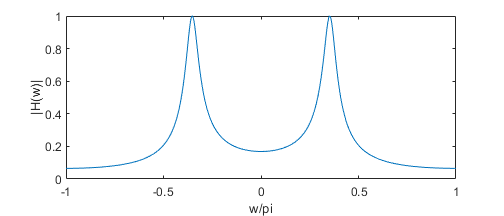

% Enter your code below and uncomment the following line(s)
figure('Position',[0,0,7,3]*72,'PaperPosition',[0,0,7,3]*72);
H = b ./ (1 - 0.8.*exp(-1i.*w) + 0.81.*exp(-1i*2.*w));
plot(w_plot, abs(H))
xlabel('w/pi')
ylabel('|H(w)|')

**(c)** Graph the wrapped and the unwrapped phase responses in one plot.

**MATLAB script and plot**: Use two different line styles and colors to distinguish two plots. Your plot must be in the range $-1\leq \omega/\pi \leq 1$.

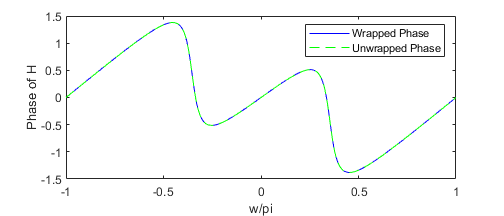

% Enter your code below and uncomment the following line(s)
figure('Position',[0,0,7,3]*72,'PaperPosition',[0,0,7,3]*72);
% Wrapped phase
plot(w_plot, angle(H), 'b-')
hold on
% Unwrapped phase
plot(w_plot, unwrap(angle(H)), 'g--')
legend('Wrapped Phase', 'Unwrapped Phase')
xlabel('w/pi')
ylabel('Phase of H')

**(d)** Determine analytically response $y[n]$ to the input $x[n] = 2\cos(\pi n/3+ 45^\deg)$. Your answer must be a closed form expression.

**Solution**: 

Because x[n] is sinusoidal and periodic in  $\Omega = \frac{\pi}{3}$:


$$y[n] = A_x|H(e^{j\Omega})|cos(\Omega n + \Phi_x + \angle H(e^{j\Omega})$$


In this problem, we evaluate $H(e^{j\omega})$ at $\frac{2 \pi}{10}$ to get:


$$y[n] = 1.775 cos(\frac{\pi n}{3} +0.804)$$


**(e)** Using MATLAB compute the steady-state response to $x[n]$ above over $0\leq n
\leq 50$ and verify your result by graphing both the output from this part and the one from (d) part in the same plot.

**MATLAB script and plot**: For verification, use **stem** plot for the analytical output and symbol 'o' in the `plot` of MATLAB output.

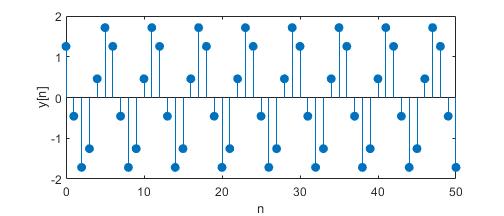

% Enter your code below and uncomment the following line(s)
figure('Position',[0,0,7,3]*72,'PaperPosition',[0,0,7,3]*72);
n = 0:50;
y = 1.775 .* cos( (pi/3).*n + (pi/4));
stem(n, y, 'filled')
xlabel('n')
ylabel('y[n]')

## Problem-2: Text Problem 5.26

 Signal $x[n]$ is periodic with fundamental period $N=10$. It is given by $x[n]=(0.8)^{n}$ over its primary interval $0\leq n < 10$. It is applied as an input to a causal LTI system with system function


$$H(z) = \frac{1-z^{-2}}{1-1.5588z^{-1}+0.81z^{-2}}.$$


**(a)** Determine the DTFS coefficients $c_{k}^{(x)}$ of $x[n]$. Express your answer as a rational function in $\mathrm{e}^{-\j2\pi/N}$.

**Solution**: 


$$c_k = \frac{1}{N}\sum^{N-1}_0x[n]e^{-j\frac{2\pi}{N}kn}$$



$$= \frac{1}{10}\sum^{9}_0(0.8)^ne^{-j\frac{2\pi}{N}kn}$$



$$= \frac{1}{10}\sum^{9}_{n=0}(0.8e^{-j\frac{2\pi}{10}k})^n$$



$$= \frac{1}{10}\Bigg( \frac{1 - 0.8^{10}}{1 - 0.8e^{-j\frac{2\pi}{10} k}} \Bigg)$$


**(b)** Determine the DTFS coefficients $c_{k}^{(y)}$ of $y[n]$. Express your answer as a rational function in $\mathrm{e}^{-\j2\pi/N}$.

**Solution**: 

Because x[n] is sinusoidal and periodic in N = 10;  f = $\frac{1}{10}$; $\Omega = \frac{2\pi}{10}$, we can just evaluate H(e^jw) at $\frac{2\pi}{10}$


$$c_k^{(y)} = c_k^{(x)} c_k^{(h)} $$



$$= \frac{1}{10}\Bigg( \frac{1 - 0.8^{10}}{1 - 0.8e^{-j\frac{2\pi}{10} k}} \Bigg)\Bigg(\frac{1-e^{\frac{-j4\pi}{10}k}}
{1 - 
1.5588e^{-j\frac{2\pi}{10}k}
+ 0.81e^{-j\frac{4\pi}}{10}k} \Bigg )$$


**(c)** Compute the steady state response $y_{\mathrm{ss}}[n]$. For the final answer, provide values of $y_{\mathrm{ss}}[n]$ over the primary period $0\leq n \leq 9$.  That is, your answer should be 10 real-valued numbers for $y_{\mathrm{ss}}[0]$ through $y_{\mathrm{ss}}[9]$.

**Solution**: 


$$y_{ss} = \sum_{k=0}^{9} c_k^{(y)} e^{j \frac{2\pi}{10} k n$$


The analytical solution is very combursome for typesetting, but the results are displayed below. 

**(d)** Using MATLAB compute and plot signals $x[n]$, $y[n]$, and$y_{\mathrm{ss}}[n]$ over $0\leq n \leq 50$ and verify your results in part (c) above. Note that $y[n]$ is obtained using the `filter` function driven by the input $x[n]$.

**MATLAB script and plots**: 

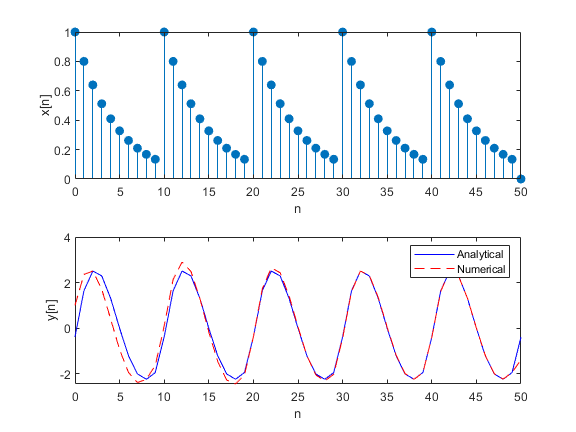

clc; clear all
% plot x
figure('Position',[0,0,8,6]*72,'PaperPosition',[0,0,8,6]*72);
subplot(2,1,1); % stem plot of 5 periods of x[n], 0 <= n <= 50
n = 0:50;
x = zeros(1, length(n));
n_idx = 0;
for k = 1:50
    x(k) = (0.8)^n_idx;
    if n_idx == 9
        n_idx = 0;
    else
        n_idx = n_idx + 1;
    end
end
stem(n, x, 'filled')
xlabel('n')
ylabel('x[n]')
subplot(2,1,2); % stem plot of y[n]
% Analytical solution
y_mat = zeros(10, length(n));
for k = 0:9
    y_mat(k+1, :) = ( (1 - 0.8^10) / (1 - 0.8*exp(-1i*2*pi/10*k))) * ( (1 - exp(-1i*4*pi/10*k)) / (1 - 1.5588*exp(-1i*2*pi/10*k) + 0.81*exp(-1i*4*pi/10*k))) .* exp((1i*k*2*pi/10) .*n);
end
y = (1/10) * sum(y_mat, 1);
% Filter solution
b = [1 0 -1]; 
a = [1 -1.5588 0.81];
y_filter = filter(b, a, x);
plot(n, real(y), 'b-')
hold on
plot(n, y_filter, 'r--')
ylabel('y[n]')
xlabel('n')
legend('Analytical', 'Numerical')

## Problem-3: Text Problem 5.30, parts (a) and (e) only

Consider a periodic signal 


$$x[n] = \sin(0.1\pi n) + \frac13\sin(0.3\pi n) + \frac15\sin(0.5\pi n).$$


For each of the following systems, determine if the system imparts (i) no distortion, (ii) magnitude distortion, and/or (iii) phase (or delay) distortion. In each case, plot first the magnitude and phase responses and then graph the input $x[n]$ and the steady state response $y_{\mathrm{ss}}[n]$ for $0\leq n\leq 60$. 

**(a)** $h[n] = \{ \underset{\uparrow}{1},-2,3,-4,0,4,-3,2,-1 \}$

**Solution**: 

Begin by shifting the whole sequence to the right by four in order to ease the calculations. The affect of this will be undone at the end.


$$h[n] = \{1,-2,3,-4, \underset{\uparrow}{0},4,-3,2,-1 \}$$



$$H(e^{j\omega}) = e^{-4j\omega} \Bigg [
(e^{4j\omega} - e^{-4j\omega}) -2
(e^{3j\omega} - e^{3j\omega}) + 3
(e^{2j\omega} - e^{-3j\omega}) -4
(e^{j\omega} - e^{-j\omega})
\Bigg ]$$



$$=  e^{-4j\omega} \Bigg[
2jsin(4\omega) -
4jsin(3\omega) +
6jsin(2\omega) -
8jsin(\omega) 
\Bigg ]$$


Thus, 


$$|H(e^{j\omega})| = 2sin(4\omega) - 4sing(3\omega) + 6sin(2\omega) -8sin(\omega)$$



$$\angle H(e^{j\omega}) = -4\omega$$


Therefore, there will be distortion in both phase and magnitude of the system

**MATLAB script and magnitude/phase plots**: Use `yyaxis left` to plot magnitude response on the left y-axis and `yyaxis right` to plot phase response on the right y-axis in the same plot. Your plots must be in the range $-1\leq \omega/\pi \leq 1$.

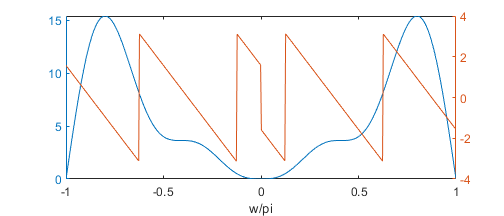

% Enter your code below and uncomment the following line(s)
w = linspace(-pi, pi, 500);
H = 1 -2.*exp(-1i.*w) +3.*exp(-2i.*w) -4.*exp(-3i.*w) +4.*exp(-5i.*w) -3.*exp(-6i.*w) +2.*exp(-7i.*w) -1.*exp(-8i.*w);
figure('Position',[0,0,7,3]*72,'PaperPosition',[0,0,7,3]*72);
yyaxis left; % plot magnitude response on the left y-axis
plot(w/pi, abs(H))
hold on
test = exp(4i.*w) .* ( (2i.*sin(4.*w)) - (4i.*sin(3.*w)) + (6i.*sin(2.*w)) -8i.*sin(1.*w));
% plot(abs(test))
yyaxis right; % plot phase response on the right y-axis
plot(w/pi, angle(H))
xlabel('w/pi')

**MATLAB script and signal plots**: Graph $x[n]$ and $y_{\mathrm{ss}}[n]$ on the same plot. Use `stem` for $x[n]$ and `plot` with marker `'o:'` for $y_{\mathrm{ss}}[n]$.

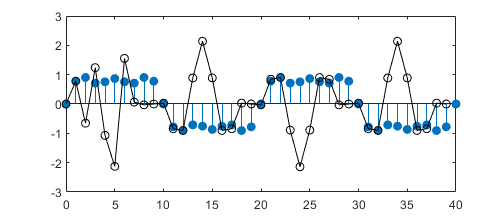

% Enter your code below and uncomment the following line(s)
n = 0:40;
x = sin(0.1*pi.*n) + (1/3) .* sin(0.3*pi.*n) +(1/5) *sin(0.5*pi.*n);
h = [1 -2 3 -4 0 4 -3 2 -1];
[y, ny] = conv0(h, [0 1 2 3 4 5 6 7 8], x, n);
figure('Position',[0,0,7,3]*72,'PaperPosition',[0,0,7,3]*72);
stem(n, x, 'filled')
hold on
plot(ny(1:40), y(1:40), 'ko-')

**(e)** $H(z) = \frac{1+1.778z^{-2}+3.1605z^{-4}}{1+ 0.5625z^{-2}+0.3164z^{-4}}$

**Solution**: 

We will keep the expression in the z-domain and evaluate at $e^{j\omega}$ later in the problem. Begin by expanding this expression using residuez function:


$$H(z) = 9.9889 + 
\frac{-2.472 - 0.6737j}{1 + (-0.3750 + 0.6495j)z^{-1}} + 
\frac{-2.472 + 0.6737j}{1 + (-0.3750 - 0.6495j)z^{-1}} + 
\frac{-2.472 + 0.6737j}{1 + (-0.3750 + 0.6495j)z^{-1}} +
\frac{-2.472 - 0.6737j}{1 + (-0.3750 - 0.6495j)z^{-1}}$$



$$=9.9889 +
 \frac{-4.9440}{1 + (-0.3750 + 0.6495j)z^{-1}} + 
 \frac{-4.9440}{1 + (-0.3750 - 0.6495j)z^{-1}}$$



$$= 9.9889 + 
\frac{-4.9440}{1+0.75e^{j2.0944}z^{-1}} +
\frac{-4.9440}{1+0.75e^{-j2.0944}z^{-1}}$$


It can be observed from the plots of magnitude and phase that there will be distortion in both domains

**MATLAB script and magnitude/phase plots**: Use `yyaxis left` to plot magnitude response on the left y-axis and `yyaxis right` to plot phase response on the right y-axis in the same plot. Your plots must be in the range $-1\leq \omega/\pi \leq 1$.

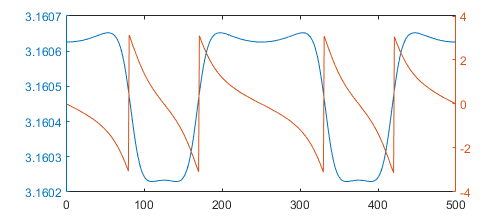

% Enter your code below and uncomment the following line(s)
w = linspace(-pi, pi, 500);
z = exp(1i.*w);
H = (1 + 1.778.*z.^-2 + 3.1605.*z.^-4) ./ (1 + 0.5625.*z.^-2 + 0.3164.*z.^-4);
test = 9.9889 - (4.9440) ./ (1 + 0.75*exp(1i*2.0944) .* z.^-1) - (4.9440) ./ (1 + 0.75*exp(-1i*2.0944) .* z.^-1);
figure('Position',[0,0,7,3]*72,'PaperPosition',[0,0,7,3]*72);
yyaxis left; % plot magnitude response on the left y-axis
plot(abs(H))
hold on

yyaxis right; % plot phase response on the right y-axis
plot(angle(H))

**MATLAB script and signal plots**: Graph $x[n]$ and $y_{\mathrm{ss}}[n]$ on the same plot. Use `stem` for $x[n]$ and `plot` with marker `'o:'` for $y_{\mathrm{ss}}[n]$.

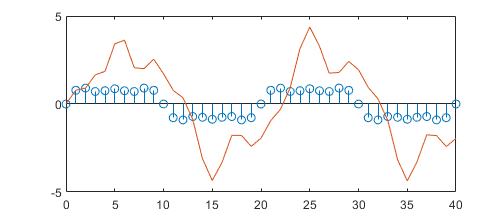

% Enter your code below and uncomment the following line(s)

figure('Position',[0,0,7,3]*72,'PaperPosition',[0,0,7,3]*72);
y = filter([1 0 1.778 0 3.1605], [1 0 0.5625 0 0.3164], x);
stem(n, x)
hold on
plot(n, y)

## Problem-4: Text Problem 5.37

Compute and plot the phase response using the functions `freqz`/`angle`, `phasez`, `unwrap`, and `phasedelay` for the following systems. Your plots must be in the range $0\leq \omega/\pi \leq 1$.

**(a)** The pure delay $y[n]=x[n-15]$.

**Solution**: 


$$Y(e^{j\omega}) = e^{-j15\omega}X(e^{j\omega})$$



$$-15\omega$$


**MATLAB script and phase plots**:

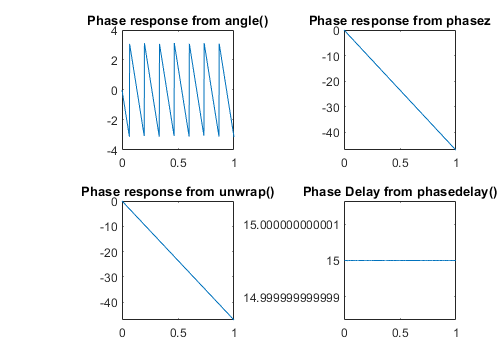

w = linspace(0, pi, 500);
H = exp(-15*1i.*w);
b = zeros(1, 16);
b(16) = 1;
figure('Position',[0,0,7,5]*72,'PaperPosition',[0,0,7,5]*72);
subplot(2,2,1); % Plot phase response using freqz/angle approach
plot(w/pi, angle(H))
title('Phase response from angle()')
subplot(2,2,2); % Plot phase response using phasez function
[out2, w2] = phasez(b, 1); 
plot(w2/pi, out2)
title('Phase response from phasez')
subplot(2,2,3); % Plot phase response using unwrap function
phase_u = unwrap(angle(H));
plot(w/pi, phase_u)
title('Phase response from unwrap()')
subplot(2,2,4); % Plot phasedelay using phasedelay function
[out4, w4] = phasedelay(b, 1);
plot(w4/pi, out4)
title('Phase Delay from phasedelay()')

**Comment on your results above**: 

**(b)** The system defined by


$$H(z) = \frac{1+z^{-1}+z^{-2}+z^{-3}}{1+0.9z^{-1}+0.81z^{-2}+0.927z^{-3}}, \quad\text{ROC includes unit circle}.$$


**MATLAB script and phase plots**:

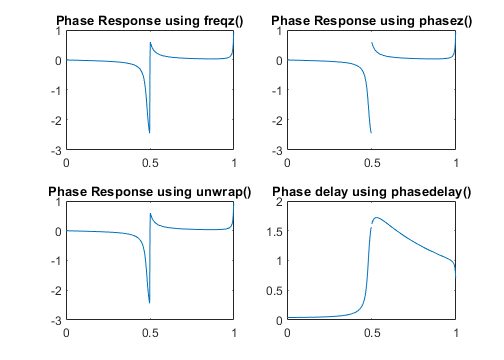

% Enter your code below and uncomment the following line(s)
b = [1 1 1 1];
a = [1 0.9 0.81 0.927];
figure('Position',[0,0,7,5]*72,'PaperPosition',[0,0,7,5]*72);
subplot(2,2,1); % Plot phase response using freqz/angle approach
[out1, w1] = freqz(b, a);
plot(w1/pi, angle(out1))
title('Phase Response using freqz()')

subplot(2,2,2); % Plot phase response using phasez function
[out2, w2] = phasez(b, a);
plot(w2/pi, out2)
title('Phase Response using phasez()')

subplot(2,2,3); % Plot phase response using unwrap function
out3 = unwrap(angle(out1));
plot(w1/pi, out3)
title('Phase Response using unwrap()')

subplot(2,2,4); % Plot phasedelay using phasedelay function
[out4, w4] = phasedelay(b, a);
plot(w4/pi, out4)
title('Phase delay using phasedelay()')

**Comment on your results above**: 

    The results for all functions are the same for the first problem, but differ for the second system function. The n-point built-in functions seem to skip the major discontinuities and jump at $\pi/2$.

## Problem-5: Text Problem 5.40

Consider a second order IIR notch filter specification that satisfies the following requirements: (1) the magnitude response has notches at $$\omega_{1,2}=\pm2\pi/3$$; (2) The maximum magnitude response is $1$; (3) the magnitude response is approximately $$1/\sqrt{2}$$ at frequencies $$\omega_{1,2}\pm0.01$$.

**(a)** Using the pole-zero placement approach determine locations of two poles and two zeros of the required filter and then compute its system function $H(z)$ as a rational function in $z^{-1}$ form and the corresponding difference equation.

**Solution**: 

To meet the notch requirements, we need zeros at $\pm 2\pi/3$. 

To meet requirement (2), we will scale the function by a constant a = max( |H| )

To meet requirement (3), we will add poles to  $2\pi/3 - 0.01$ and scale them by sqrt(2). We set r=0.99 so the magnitude is approximately 1 near these poles


$$H = a \frac{(1-e^{-j2\pi/3}z^{-1}){(1-e^{j2\pi/3}z^{-1})}}
{\sqrt{2}(1-re^{j(2\pi/3+0.01)}z^{-1})(1-re^{j(-2\pi/3+0.01)}z^{-1})}$$


With the help of the matylab code below, it is shown that the scale factor is $\frac{1}{1.0967$

** (b)** Graph the magnitude response of the filter and verify the given requirements.

**MATLAB script and plot**: Your plot must be over $-1\leq\omega/\pi\leq 1$ interval.

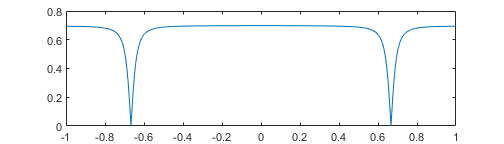

figure('Position',[0,0,7,2]*72,'PaperPosition',[0,0,7,2]*72);
w = linspace(-pi, pi, 500000);
a = 1;
r = 0.9;
H = a .* ( (1-exp(-2i*pi/3).*exp(-1i.*w)) .*  (1-exp(2i*pi/3).*exp(-1i.*w)) ) ./ (sqrt(2)/r.*(1-r*exp(((-2i*pi)/3)+0.01).*exp(-1i.*w)) .*  (1-r*exp(((2i*pi)/3)+0.01).*exp(-1i.*w)));
plot(w/pi, abs(H))

% Print Scale factor
a = max(abs(H))

a = 0.6980

fprintf('At frequency %f the magnitude is %f', w(idc), abs(H(idc)))

At frequency 2.104400 the magnitude is 0.072910

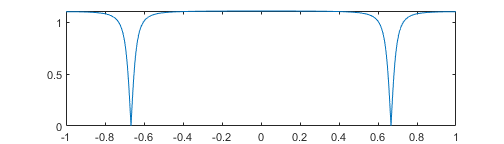

% Find closest value to 0.01 + 2pi/3 and find r to make it 1/sqrt(2)
test = (2*pi/3) + 0.01;
[val, idc] = min(abs(w - test));

% Re-run
H = (1/a) .* ( (1-exp(-2i*pi/3).*exp(-1i.*w)) .*  (1-exp(2i*pi/3).*exp(-1i.*w)) ) ./ (sqrt(2).*(1-r*exp(((-2i*pi)/3)+0.01).*exp(-1i.*w)) .*  (1-r*exp(((2i*pi)/3)+0.01).*exp(-1i.*w)));
plot(w/pi, abs(H))

**Verification**: 

It can be observed from the graphs, that there are clear stopbands at 0.66 on the x axis or $\frac{2\pi}{3}$. Similarly, the printout at the bottom shows that the magnitude at 2.104 ~ $\frac{2 \pi}{3} + 0.01$ is 0.707 ~ $\frac{1}{\sqrt{2}}$

(c) Graph phase and group-delay responses in one plot.

**MATLAB script and plot**: Your plot must be over $-1\leq\omega/\pi\leq 1$ interval.

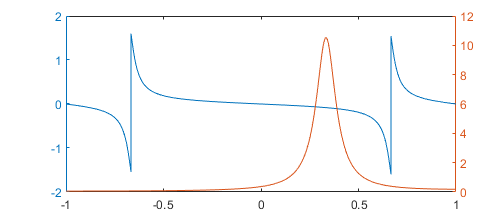

% filter coefficients
b = (1/a) .* conv([1 -exp(-2i*pi/3)], [1 -exp(2i*pi/3)]);
a = sqrt(2) .* conv([1 -r*exp(((-2i*pi)/3)+0.01)], [1 -r*exp(((2i*pi)/3)+0.01)]);

% Plots
figure('Position',[0,0,7,3]*72,'PaperPosition',[0,0,7,3]*72);
yyaxis left; % plot phase response on the left y-axis
plot(w/pi, angle(H));
yyaxis right; % plot group=delay response on the right y-axis
g = grpdelay(b, a, 500000);
plot(w/pi, g)

**(d)** To study the effectiveness of the above designed notch filter, consider a sinusoidal signal $\cos(0.1\pi n)$ that is contaminated by a high frequency powerline interference $5\cos(2\pi n/3 + \pi/4)$. So, let the input to the notch filter be $x[n] = \cos(0.1\pi n) + 5\cos(2\pi n/3+\pi/4)$. Using the `filter` function, compute $y[n]$ over $0\leq n\leq 2000$. Display both $x[n]$ and $y[n]$ over $1950\leq n\leq 2000$ (steady-state part) in one figure and comment on the effectiveness of the designed notch filter.

**MATLAB script and plots**: Use the `plot` command to depict continuous plots.

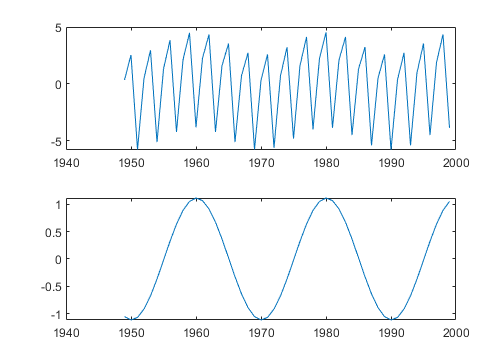

figure('Position',[0,0,7,5]*72,'PaperPosition',[0,0,7,4]*72);
subplot(2,1,1); % plot x[n], 1950 <= n <= 2000
n = 0:2000;
x = cos(0.1*pi.*n) + 5.* cos((2*pi/3).*n + pi/4);
plot(n(1950:2000), x(1950:2000))
subplot(2,1,2); % plot y[n], 1950 <= n <= 2000
y = filter(b, a, x);
plot(n(1950:2000), y(1950:2000))

**Comment**: 

With this notch filter, we were able to remove almost all noticable artifacts of the high frequency distortion.

## Problem-6: Text Problem 5.55 parts (a) and (b) only

Determine the system function and plot magnitude and phase responses of the following systems. Use the pole-zero pattern to explain the shape of their magnitude responses.

**(a)** $y[n]=x[n]-x[n-2]-0.81y[n-2]$:

**Solution**: 


$$\frac{1 - e^{-2j\omega}}{1+e^{-2j\omega}}$$


**MATLAB script and plots**: Use the range $-1\leq\omega/\pi\leq 1$ for plotting.

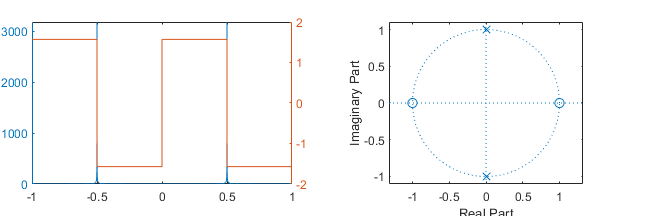

w = linspace(-pi, pi, 5000);
H = (1-exp(-2i.*w)) ./ (1 + exp(-2i.*w));
figure('Position',[0,0,9,3]*72,'PaperPosition',[0,0,9,3]*72);
subplot('Position',[0.05,0.15,0.4,0.75]); % mgnitude and phase plots
yyaxis left; % magnitude plot
plot(w/pi, abs(H))
yyaxis right; % phase plot
plot(w/pi, angle(H))
subplot('Position',[0.6,0.15,0.3,0.75]); % polse-zero pattern
zplane([1 0 -1], [1 0 1])

**Comments on responses**:

From the system function, we would expect the magnitude to spike near $\pm  \frac{\pi}{2}$ becasue there are poles there and be zero near 0 and $\pi$ because there are zeros there. This is supported by the magnitude plot 

**(b)** $y[n]=x[n]-x[n-4]+0.6561y[n-4]$:

**Solution**: 


$$\frac{1 - e^{-4j\omega}}{1+0.6561e^{-4j\omega}}$$


**MATLAB script and plots**: Use the range $-1\leq\omega/\pi\leq 1$ for plotting.

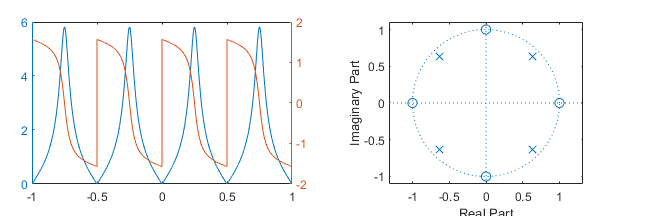

H = (1-exp(-4i.*w)) ./ (1 + 0.6561.*exp(-4i.*w));
figure('Position',[0,0,9,3]*72,'PaperPosition',[0,0,9,3]*72);
subplot('Position',[0.05,0.15,0.4,0.75]); % mgnitude and phase plots
yyaxis left; % magnitude plot
plot(w/pi, abs(H))
yyaxis right; % phase plot
plot(w/pi, angle(H))
subplot('Position',[0.6,0.15,0.3,0.75]); % polse-zero pattern
zplane([1 0 0 0 -1], [1 0 0 0 0.6561])

**Comments on responses**:

From the system function, we see that there should be four peaks and four zeros. The zeros should be located at the roots of the numerator which are [1, 1i, -1, -1i] or [0, $\pi/2$, -1, -$\pi/2$, 1] similarly, it will spike at the roots of the denominator which correspond to the peaks shown in the graph.

## Problem-7:

Signal $x_\mathrm{c}(t)= 5\mathrm{e}^{\j40\pi t} + 3\mathrm{e}^{-\j70\pi t}$ is sampled periodically with sampling interval $T = 0.02$sec to obtain the discrete-time signal $x[n]$. It is then passed through an ideal DAC to obtain $y_\mathrm{c}(t)$. 

**(a)** Determine the CTFT $X_\mathrm{c}(\j\Omega)$ of $x_\mathrm{c}(t)$ and plot it as a function of $\Omega$ in rad/sec. Your plot must cover the range of $-100\leq \Omega/\pi\leq 100$. 

**Solution**: 


$$X_c(j\Omega) = 5\delta(\Omega-40\pi) +  3\delta(\Omega + 70 \pi) $$


**MATLAB script and plot**: The plot below contains impulses which are generally shown as vertical arrows. Use the `stem` function with `'marker'` symbol `'^'` to show arrows in a MATLAB plot. Alternatively, sketch you own plot by hand and then insert the sketch as an image after scanning (smartphone snap is not acceptable).

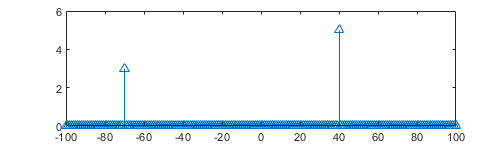

figure('Position',[0,0,7,2]*72,'PaperPosition',[0,0,7,2]*72);
w = -100:100;
h = zeros(1, length(w));
h(31) = 3; h(141) = 5;
stem(w, h, '^')

**(b)** Determine the DTFT $X(\mathrm{e}^{\j\Omega T})$ of $x[n]$ using the aliasing formula (6.12) in the textbook and plot it as a function of $\Omega$ in rad/sam. Your plot must cover the range of $-100\leq \Omega/\pi\leq 100$. 

**Solution**: 


$$X(e^{j\Omega T}) = \frac{1}{T} \sum X_c(j(\frac{\omega}{T} - \frac{2\pi}{T} k))$$


**MATLAB script and plot**: The plot below contains impulses which are generally shown as vertical arrows. Use the `stem` function with `'marker'` symbol `'^'` to show arrows in a MATLAB plot. Alternatively, sketch you own plot by hand and then insert the sketch as an image after scanning (smartphone snap is not acceptable).

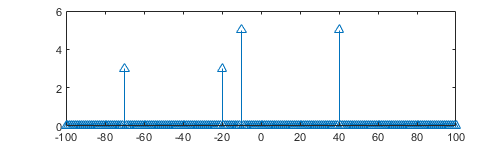

figure('Position',[0,0,7,2]*72,'PaperPosition',[0,0,7,2]*72);
X = zeros(length(w), 1);
T = 0.02;
h = zeros(1, length(w));
h(31) = 3; h(141) = 5; h(91) = 5; h(81) = 3;
stem(w, h, '^')

**(c)** Determine the reconstructed signal $y_\mathrm{c}(t)$.

**Solution**: 


$$Y(e^{j\omega})  = 3\delta[\omega+70] + 3\delta[\omega +20] + 5\delta[\omega +10] + 5\delta[\omega -40]$$


**(d)** Explain if $y_\mathrm{c}(t)$ is identical to $x_{\mathrm{c}}(t)$.

**Answer**: 

The sampling frequency is below the Nyquist frequency, so the two will not be identical. This can be seen in both parts b and c, as the sampels overlap in part b and the reconstruction formula does not remove all affects of nT

## Problem-8: Text Problem 6.22 (b)

Signal $x_{\mathrm{c}}(t)= 3 + 2\sin(16\pi t) + 10\cos(24\pi t)$ is sampled at a rate of $F_\mathrm{s}$ to obtain the discrete-time signal $x[n]$. For the sampling rate of $F_\mathrm{S}=20$ Hz (i) determine the DTFT $X\bigl(\mathrm{e}^{\j2\pi F/20}\bigr)$ of $x[n]$; (ii) plot its magnitude as a function of $F$ in Hz; and (iii) explain if $x_\mathrm{c}(t)$ can be recovered from $x[n]$.

**(i)** DTFT $X\bigl(\mathrm{e}^{\j2\pi F/20}\bigr)$ of $x[n]$.

**Solution**: 


$$3 + \frac{1}{j}(e^{8F} - e^{-8F}) + 5(e^{-12F} + e^{12F})$$


Therefore: 


$$\left\lbrack \begin{array}{cc}
3 & F=0\\
j & F=8\\
-j & F=-8\\
5 & F=12\\
5 & F=-12\\
0 & \mathrm{else}
\end{array}\right\rbrack$$


**(ii)** Plot of $\bigl\vert X\bigl(\mathrm{e}^{\j2\pi F/20}\bigr)\bigr\vert$ as a function of $F$ in Hz.

**MATLAB script and plots**: This plot contains impulses (generally shown as vertical arrows). Use the `stem` plot with `'marker'` symbol `'^'` to show arrows in a MATLAB plot. Alternatively, sketch you own plot by hand and then insert the sketch as an image after scanning (smartphone snap is not acceptable). Your plot must cover range of $-30\leq F\text{ in Hz}\leq 30$. 

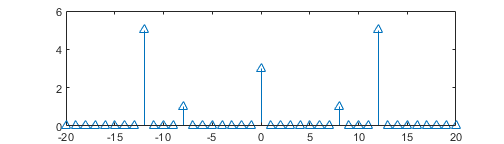

F = -20:20;
mag_x = 3*delta(-20, 0, 20) + 1*delta(-20, 8, 20) + 1*delta(-20, -8, 20) + 5*delta(-20, 12, 20) + 5*delta(-20, -12, 20);
figure('Position',[0,0,7,2]*72,'PaperPosition',[0,0,7,2]*72);
stem(F, mag_x, '^')

**(iii)** Can $x_\mathrm{c}(t)$ be recovered from $x[n]$? Explain clearly.

**Answer**: 

It can not be recovered at a sample rate of 20 Hz, because this is below the Nyquist frequency of at least 24 Hz. Sampling at this rate will cause aliasing, as there will be overlap between the spectra. 

## Problem-9: Text Problem 6.26

Consider a continuous-time signal $x_\mathrm{c}(t)= 3\cos(2\pi F_{1} t + 45^{\circ})+3\sin(2\pi F_{2} t).$ It is sampled at $t=0.001n$ to obtain $x[n]$ which is then applied to an ideal DAC to obtain the continuous-time signal $y_{\mathrm{r}}(t)$.

**(a)** For $F_{1}=150$ Hz and $F_{2}=400$ Hz, determine $x[n]$ and graph its samples along with the signal $x_\mathrm{c}(t)$ in one plot. Choose plotting interval of $-10\leq t,\text{ms} \leq 10$.

**Solution**: 


$$= 3cos(2\pi 150(0.001n)+\frac{\pi}{4}) + 3 sin(2\pi400(0.001n))$$



$$=3cos(0.3\pi n + \frac{\pi}{4}) + 3 sin(0.8\pi n)$$


**MATLAB script and plot**:

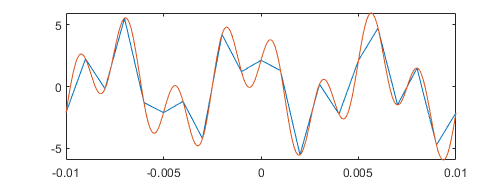

t = -10:0.01:10;
t = t*10^-3;
n = -10:10;
n_idx = n*10^-3;
figure('Position',[0,0,7,2.5]*72,'PaperPosition',[0,0,7,2.5]*72);
xc = 3.*cos(300*pi.*t + (pi/4)) + 3.*sin(800*pi.*t);
xn = 3.*cos(0.3*pi.*n + (pi/4)) + 3.*sin(0.8*pi.*n);
plot(n_idx,xn)
hold on
plot(t, xc)

**(b)** Determine $y_{\mathrm{r}}(t)$ for the above $x[n]$ as a sinusoidal signal. Graph and compare it with $x_\mathrm{c}(t)$.

**Solution**: 

Yc is obtained by applying a low-pass filter to X($e^{j\omega}$). Thus, 


$$Y(e^{j\omega}) = rect(0, 1000) X(e^{j\omega})$$


Because the signal is properly sampled, there is no aliasing and we can reconstruct y as:


$$y(t) = 3cos(300\pi t+ \frac{\pi}{4}) + 3 sin(800\pi t)$$


**MATLAB script and plot**: Plot both signals in one plot using different line styles or color. Use plotting interval of $-10\leq t,\text{ms} \leq 10$.

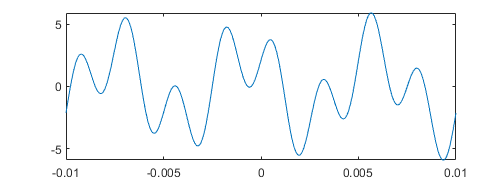

t = -10:0.1:10;
t = t*10^-3;
figure('Position',[0,0,7,2.5]*72,'PaperPosition',[0,0,7,2.5]*72);
y = 3*cos(300*pi.*t + (pi/4)) + 3*sin(800*pi.*t);
plot(t,y)

**(c)** Repeat (a) and (b) for $F_{1}=300$ Hz and $F_{2}=700$ Hz. Comment on your results.

**Determination of **$x[n]$: 


$$x[n] = 3 cos(2\pi300(0.001n) + \frac{\pi}{4}) + 3sin(2\pi700(0.001n))$$



$$x[n] = 3cos(0.6\pi n + \frac{\pi}{4}) + 3sin(1.4\pi n)$$


**MATLAB script and plot**: Show $x[n]$ (using `stem`) and $x_\mathrm{c}(t)$(using `plot`) in one figure. Choose plotting interval of $-10\leq t,\text{ms} \leq 10$.

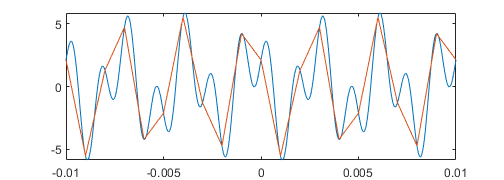

figure('Position',[0,0,7,2.5]*72,'PaperPosition',[0,0,7,2.5]*72);
t = -10:0.01:10;
t = t*10^-3;
n = -10:10;
n_idx = n*10^-3;
% Calculations
xc = 3*cos(2*pi*300.*t + (pi/4)) + 3*sin(2*pi*700.*t);
xn = 3*cos(0.6*pi.*n + (pi/4)) + 3*sin(1.4.*pi*n);
% Plots
plot(t, xc)
hold on
plot(n_idx, xn)

**Determination of **$y_\mathrm{r}(t)$:

Begin by determining the basic Fourier Transform of the signal:


$$X(e^{j\omega}) = 

\frac{3}{2} [e^{j0.6\pi \omega} + e^{-j0.6\pi \omega}]
+\frac{3}{2j} [e^{j1.4\pi \omega} - e^{-j1.4\pi \omega}]$$


For reconstruction, we need only consider components between $[- \pi, \pi]$ and therefore must only  conside $k = \pm1$.

Combing, we get:


$$3 [\frac{e^{j0.6\pi \omega} + e^{-j0.6\pi \omega}}{2} ] + 3[\frac{e^{-j0.6\pi \omega} - e^{j0.6\pi \omega}}{2j} ]$$


= $3cos(0.6\pi n + \frac{\pi}{4}) - 3sin(0.6\pi n)$


$$= 3cos(600 \pi t + \pi/4) - 3sin(600\pi t)$$


**MATLAB script and plot**: Plot both $y_\mathrm{r}(t)$ and $x_\mathrm{c}(t)$ signals in one plot using different line styles or color. Use plotting interval of $-10\leq t,\text{ms} \leq 10$.

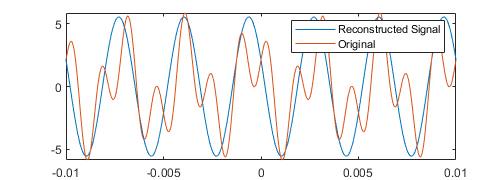

t = -10:0.01:10;
t = t*10^-3;
figure('Position',[0,0,7,2.5]*72,'PaperPosition',[0,0,7,2.5]*72);
yr = 3*cos(600*pi.*t + (pi/4)) - 3*sin(600*pi.*t);
plot(t, yr);
hold on
plot(t, xc)
legend('Reconstructed Signal', 'Original')

Can $x_\mathrm{c}(t)$ be recovered from $x[n]$?

**Answer**:

In this case, x could not be reconstructed because the sampling rate was below the Nyquist rate.

## Problem-10: 

We implement the following analog filter using an embedded discrete filter.

The sampling rate in the A/D and D/A is 8000 sam/sec, and the impulse response is $h[n] =\left(-0.9\right) ^nu[n].$

**(a)** What is the digital frequency, $-\pi<\omega_0\leq \pi$ (in rad/sam), that is present in $x[n]$ if $x_\mathrm{c}(t) =10\cos(10000\pi t)$?

**Solution**: 

T = $1 /8000 (sec/sam)$


$$x[n] = 10 cos( \frac{10000}{8000} \pi n)$$



$$= 10cos(1.25\pi n)$$


Thus, the digital frequency is 0.625$\pi
$

**(b)** Determine the steady-state output $y_\mathrm{c}( t)$ if $x_\mathrm{c}(t) = 10\cos(10000\pi t)$. Is there aliasing?

**Solution**: 


$$Y_c = 5[\delta[\omega + 1.25] + \delta[\omega - 1.25]]\frac{1}{1+0.9e^{-j\omega}$$



$$= \frac{5}{1+0.9e^{-1.25j}} + \frac{5}{1+0.9e^{1.25j}}$$


Yes, there will be aliasing in this system. To avoid aliasing, the DAC would have to be at least 20000 sam/sec

**(c)** Determine the steady-state output $y_\mathrm{c}(t)$ if $x_\mathrm{c}(t) = 5\sin(8000\pi t)$. Is there aliasing.

**Solution**: 

**(d)** Find two other analog signals $$x_\mathrm{c}\left( t\right)$, with different analog frequencies, that will give the same steady-state output $y_\mathrm{c}(t)$ when $x_\mathrm{c}(t) =10\cos(10000\pi t)$ is applied.

**Solution**: 

$10 cos(20000\pi )$ because $\frac{20000}{8000*2} = 1.25$

$10 cos(30000\pi t)$ because $\frac{30000}{8000*3} = 1.25$

**(e)** To prevent aliasing, a prefilter would be required to process $x_\mathrm{c}\left( t\right)$ before it passes to the A/D converter. What type of filter should be used, and what should be the largest cutoff frequency (in Hz) that would work for the given configuration?

**Solution**: 

4 kHz

##  